tic
parfeval(@estimateruntime,1);
M = load('TEM_PYTHON\DSOX1204G_TEM_pat1.mat');
%M = M(:,2)';
og = M.y1; 
M = M.y3';
[x,tau] = findpeaks(M,'MinPeakDistance',40,'MinPeakHeight',1);
M = tau/length(M);
%M = readmatrix('C:\Users\97253\PycharmProjects\Pan_denoiser_test\tn.csv')';
%M = readmatrix('scope_34_ecg_best.csv');
%M = readmatrix('scopehw1.csv');
%M = readmatrix('hwscope2.csv'); 
%M = load('ecg_HW_v2.mat');
%M = readmatrix('scope_29.csv');
%M = M.C; 
%x`M = M(3:end,2);
%M = circshift(M,-500); 
%M = resample(M,33,100); 
%M = resample(M,601,661);
%M = M'; 
%C = readmatrix('scope_18.csv');
%M = C(3:end,4)./max(C(3:end,4));
%M2 = C(200:800,3)./max(C(200:800,3));
%M = M'; 
%M = interp(M,10); 
%M = tn;



%[~,locs] = findpeaks(M,'MinPeakDistance',13); 
%tn = locs/length(M); 
%Ntn = length(tn);
%D = zeros(1,length(M)); 
%D(locs) = max(M); 

tn = M;

%tn = tn+0.05;%optional 
%M = resample(M,500,2000);
%M = readmatrix('C:\Users\97253\PycharmProjects\Pan_denoiser_test\signal.csv');
%M = M(:,2)';
%tn2 =M(2:end);  %tn2-0.016;
%1pullse: b=1.805;d=0.993; kappa=0.01;
%2pulse: b=1.690;d=0.929; kappa=0.010;
%3pulses:b=1.655; d=0.910; kappa=0.01;
%4pulses: b=1.780; d=0.979; kappa=0.010;
%b=0.780; d=0.979; kappa=0.010;
%b= 2.275;d= 1.133;kappa = 0.031;
%b=.65; d=1.133; kappa=0.014;
%b=.52; d=1.133; kappa=0.014;
%b=.55; d=1.133; kappa=0.014;
b=1.75;
d=1.133;
kappa=0.014;
b=0.78;d=0.99;kappa=0.018;
dt = 1/50; 
yDel = -b*diff(tn) + kappa*d;
K =5;
T = 1; 
N =50; 
K = 4*K+2; 
w0 = 2*pi/T;

%F = exp(1j*w0*tn(2:end)'*([-K:-1,1:K]))-exp(1j*w0*tn(1:end-1)'*[-K:-1,1:K]);
%s = T./(1j*2*pi*([-K:-1,1:K]));
%S = diag(s);

%z = cumsum(yDel);
%A = exp(1j*w0*tn(2:end)'*(-K:K));
%s = T./(1j*2*pi*(-K:K)); s(K+1) = 1;
%S = diag(s);
%ytnHat = pinv(A*S)*z';

% 
 F = exp(1j*w0*tn(2:end)'*(-K:K)) - exp(1j*w0*tn(1:end-1)'*(-K:K));
 F(:,K+1) = tn(2:end) - tn(1:end-1);
 s = T./(1j*2*pi*(-K:K)); s(K+1) = 1;
 S = diag(s);

ytnHat = pinv(F*S)*yDel';
ytnHat = ytnHat'*N;
spectrum = transpose(conj(ytnHat(K+1:end)));
spectrum = cadzow(spectrum,inf,K); 


Cadzow iteration 1 (rank is 12, target is Inf).

save('TEM_PYTHON\spectrum.mat','spectrum');
disp("saved!");

saved!



xyo = system('python3 TEM_PYTHON\temp1.py');

56 
56 
23 
23 
23 
200 
(200, 201) 
(399, 201) 
(399, 201) 
(399,) 
(399, 201) 
0.05901873274638685 


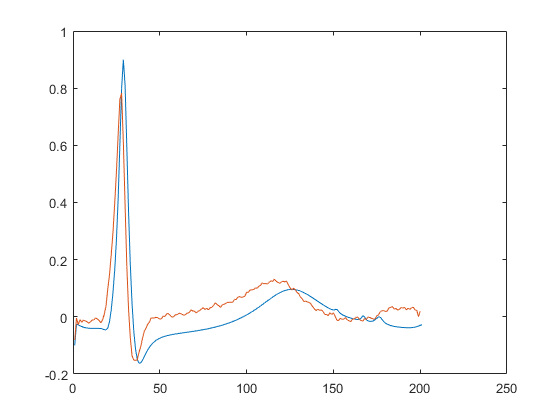



outputsignal = readmatrix('pulse11_100_hw_recon.csv');
plot((outputsignal(:,2)-0.1)/max(outputsignal(:,2)));hold on;plot((resample(og,200,length(og))-0.2)./max(og));

toc

Elapsed time is 12.023837 seconds.
